clc
clear
close all
file = load("C:\Users\frede\Desktop\Final tests\Prototype system test\Test 4. no control\in5, in5, out0 with control\Test 1\Results.mat")

file = struct with fields:
    data: [1×1 Simulink.SimulationData.Dataset]


data = file.data

data = Simulink.SimulationData.Dataset 'data' with 2 elements

                          Name                             BlockPath 
                          _______________________________  _________ 
    1  [1x1 Dataset]      Run 2: valveWithHighResCommands  ''       
    2  [1x1 Dataset]      Run 3: valveWithHighResCommands  ''       

  - Use braces { } to access, modify, or add elements using index.


data = data.getElement(1)

data = Simulink.SimulationData.Dataset 'Run 2: valveWithHighResCommands' with 12 elements

                         Name                    PropagatedName          BlockPath                                
                         ______________________  ______________________  ________________________________________ 
    1  [1x1 Signal]      Bus Creator6            Bus Creator6            valveWithHighResCommands/31 data        
    2  [1x1 Signal]      Bus Creator7            Bus Creator7            valveWithHighResCommands/34 data        
    3  [1x1 Signal]      control 41              control 41              ...HighResCommands/Flow and control LU41
    4  [1x1 Signal]      control 43              control 43              ...HighResCommands/Flow and co

Names = data.getElementNames

Names = 12×1 cell array
    {'Bus↵Creator6'          }
    {'Bus↵Creator7'          }
    {'control 41'            }
    {'control 43'            }
    {'control 44'            }
    {'Manual valve openings '}
    {'Controller:4'          }
    {'Tank 44 data'          }
    {'Valve openings'        }
    {'source_flows'          }
    {'Tank 41 data'          }
    {'Tank 43 data'          }


numberOfPlots = 4

numberOfPlots = 4

PlotFontSize = 8

PlotFontSize = 8

LegendFontSize = 7

LegendFontSize = 7

PlotThickness = 1.3

PlotThickness = 1.3000

LU41Color = "#0072bd"

LU41Color = "#0072bd"

LU43Color = "#edb120"

LU43Color = "#edb120"

LU44Color = "#fe330a"

LU44Color = "#fe330a"

Xspan = [0 350]

Xspan =      0   350



RemainingCapacityIndex = find(strcmp(Names,'Controller:4'),1) %7

RemainingCapacityIndex = 7

ValveOpeningsIndex = find(strcmp(Names,'Valve openings'),1)

ValveOpeningsIndex = 9

SorceflowIndex = find(strcmp(Names,'source_flows'),1) %10

SorceflowIndex = 10

LU41Index = find(strcmp(Names,'Tank 41 data'),1) %11

LU41Index = 11

LU43Index = find(strcmp(Names,'Tank 43 data'),1) %12

LU43Index = 12

LU44Index = find(strcmp(Names,'Tank 44 data'),1) %8

LU44Index = 8

LU41ControlerIndex = find(strcmp(Names,'control 41'),1) %3

LU41ControlerIndex = 3

LU43ControlerIndex = find(strcmp(Names,'control 43'),1) %4

LU43ControlerIndex = 4

LU44ControlerIndex = find(strcmp(Names,'control 44'),1) %5

LU44ControlerIndex = 5



fig = figure;
set(fig, "Units", "pixels", "Position", [100 100 600 550]);

subplot(numberOfPlots,1,1)
% Pick the data 
controller = data.getElement(RemainingCapacityIndex)

controller =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'Controller:4'
    PropagatedName: 'Controller:4'
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'outport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

RS = controller.Values

RS = struct with fields:
    R_s_44: [1×1 timeseries]
    R_s_43: [1×1 timeseries]
    R_r_41: [1×1 timeseries]


hold("on")
ax = gca;
ax.FontSize = PlotFontSize;        % tick labels
title("Remaining capacity in internal reservoir","FontSize", PlotFontSize)
ylabel({"Remaning"; "capacity (liters)"},"FontSize", PlotFontSize)
ylim([-1 30])
xlim(Xspan)
grid on
plot(RS.R_r_41,"color", LU41Color,"linewidth",PlotThickness)
plot(RS.R_s_43,"color",LU43Color,"linewidth",PlotThickness)
plot(RS.R_s_44,"color",LU44Color,"linewidth",PlotThickness)
legend("LU41","LU43","LU44","location","eastoutside","FontSize", LegendFontSize)
hold("off")

subplot(numberOfPlots,1,2)
% Pick the data 
sourceFlows = data.getElement(SorceflowIndex)

sourceFlows =   Simulink.SimulationData.Signal
  Package: Simulink.SimulationData

  Properties:
              Name: 'source_flows'
    PropagatedName: 'source_flows'
         BlockPath: [1×1 Simulink.SimulationData.BlockPath]
          PortType: 'outport'
         PortIndex: 1
            Values: [1×1 struct]


  Methods, Superclasses

Q = sourceFlows.Values

Q = struct with fields:
    Q1_1__signal_1_: [1×1 timeseries]
    Q1_1__signal_2_: [1×1 timeseries]


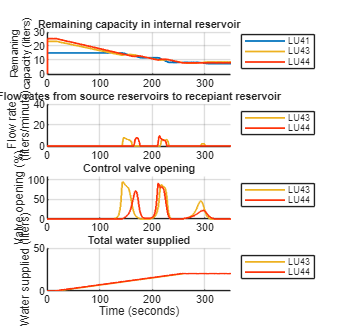

hold("on")
ax = gca;
ax.FontSize = PlotFontSize; 
title({"Flow rates from source reservoirs to recepiant reservoir"},"FontSize", PlotFontSize)
ylabel({"Flow rate"; "(liters/minute)"})
ylim([-1 40])
xlim(Xspan)
grid on
plot(Q.Q1_1__signal_2_,"color",LU43Color,"linewidth",PlotThickness)
plot(Q.Q1_1__signal_1_,"color",LU44Color,"linewidth",PlotThickness)
legend("LU43","LU44","location","eastoutside","FontSize", LegendFontSize)
hold("off")

subplot(numberOfPlots,1,3)
% Pick the data 
valve_data = data.getElement(ValveOpeningsIndex);
valve_value = valve_data.Values;

hold("on")
ax = gca;
ax.FontSize = PlotFontSize; 
title("Control valve opening","FontSize", PlotFontSize)
ylabel("Valve opening (%)")
ylim([0 110])
xlim(Xspan)
grid on
plot(valve_value.V_s_43,"color",LU43Color,"linewidth",PlotThickness)
plot(valve_value.V_s_44,"color",LU44Color,"linewidth",PlotThickness)
legend("LU43","LU44","location","eastoutside","FontSize", LegendFontSize)
hold("off")

subplot(numberOfPlots,1,4)
% Pick the data 
tank43control_data = data.getElement(LU43ControlerIndex);
tank44control_data = data.getElement(LU44ControlerIndex);
tank43control_value = tank43control_data.Values;
tank44control_value = tank44control_data.Values;

hold("on")
ax = gca;
ax.FontSize = PlotFontSize; 
title("Total water supplied","FontSize", PlotFontSize)
ylabel("Water supplied (liters)")
ylim([0 50])
xlim(Xspan)
xlabel("Time (seconds)")
grid on
plot(tank43control_value.Total_supplied__to_LU43,"color",LU43Color,"linewidth",PlotThickness)
plot(tank44control_value.Total_supplied_to_LU44,"color",LU44Color,"linewidth",PlotThickness)
legend("LU43","LU44","location","eastoutside","FontSize", LegendFontSize)
hold("off")